clc;
close all;
clear all;
s=tf('s');
T=2; %constante de systeme
Te = T/20 %période d'échantillonage

Te = 0.1000

tfinal = 10;
sys = 1/(T*s+1)

sys =
 
     1
  -------
  2 s + 1
 
Continuous-time transfer function.



Modèle dénominateur BF : méthode du modèle

xi = .7; %1/sqrt(2)
omega0=.5;

Réponse indicielle 

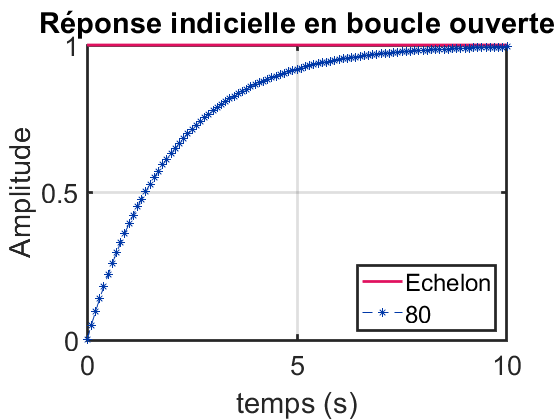

tech = (0:Te:tfinal);
[ytech]=step(1,1,tech);
[ybo,tbo]= step(sys,tech);
plot(tech,ytech,'LineStyle','-',"Color","#E0115F","LineWidth",2) 
grid, hold on;
plot(tbo,ybo,'MarkerSize',6,"Marker","*","MarkerEdgeColor","#0038A8","LineStyle","--","Color","#0038A8"); %blue
grid on;
xlabel('temps (s)');
ylabel('Amplitude');
title("Réponse indicielle en boucle ouverte")
legend('Echelon','80','location','southeast')
ax=gca;
ax.FontSize = 20;
ax.LineWidth = 2;
hold off

Définition d'un correcteur proportionnel

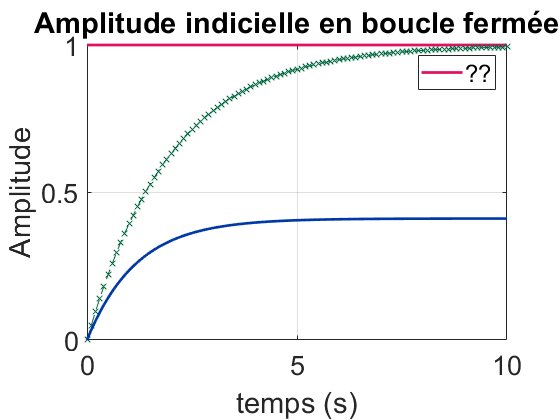

K = 10;
cor = xi;
sysbf = feedback(cor * sys,1);
[ybf,tbf]=step(sysbf,tfinal);
plot(tech,ytech,'LineStyle','-',"Color",'#E0115F',"LineWidth",2);
grid, hold on;
plot(tbo,ybo,'LineStyle',"--","Marker","x","MarkerSize",6,"Color",'#00693E');
plot(tbf,ybf,"MarkerFaceColor",'#0038A8',"LineStyle","-","Color","#0038A8",'LineWidth',2);
%plot (tbf,ybf)
xlabel('temps (s)');
ylabel('Amplitude');
title("Amplitude indicielle en boucle fermée");
legend("??");
ax=gca;
ax.FontSize=20;
hold off;

Réponse à un échelon de consigne 

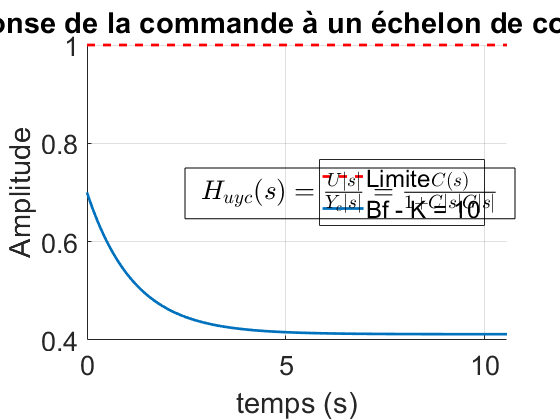

Hu_yref = feedback(cor,sys); %resultat FT
[u, tbf_u] = step(Hu_yref);
figure,
line(tbf_u([1 end]), ones(2,1), 'Color', 'red','LineStyle','--','LineWidth',2);
hold on
plot (tbf_u,u,'LineWidth',2)
grid on
xlabel('temps (s)');
ylabel('Amplitude');
title('Réponse de la commande à un échelon de consigne');
str = ('$H_{uyc}(s)=\frac{U|s|}{Y_c|s|}=\frac{C(s)}{1+C|s|G|s|}$');
dim = [0.5 0.4 0.25 0.2];
annotation('textbox',dim,'String',str,'FitBoxToText',"on",'FontSize',20,'HorizontalAlignment',"center",'Interpreter',"latex");
legend({'Limite', ['Bf - K = ' num2str(K)]},"Location","best")
ax = gca;
ax.FontSize = 20;
hold off;

Définition d'une PI mixte comme une FT

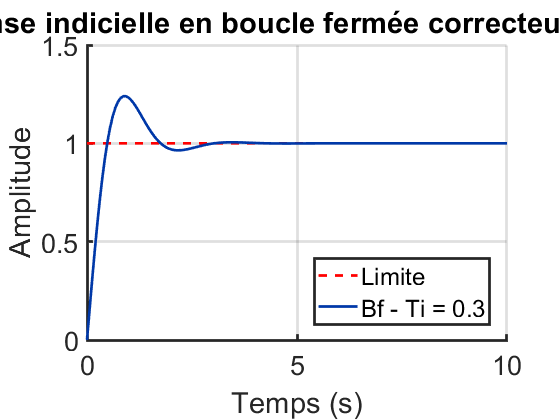

K = 5;
%se mettre sur la ligne et faire un clic droit
% 2 + 1 ... augmenter le gain avec "Increment value and run section
Ti = .3;
cor = K*(1+1/(Ti*s));
sysbf = feedback(cor*sys,1);
[ybf,tbf] = step(sysbf,tfinal);
figure;
line(tbf([1 end]), ones(2, 1),"Color",'red','LineStyle','--','LineWidth',2);
hold on;
plot (tbf,ybf,'MarkerFaceColor',"#0038A8",'LineStyle',"-","Color","#0038A8","LineWidth",2);
grid on;
xlabel("Temps (s)")
ylabel("Amplitude")
title (['Réponse indicielle en boucle fermée correcteur PI - K ' num2str(K)])
legend({'Limite', ['Bf - Ti = ' num2str(Ti)]},"Location","best")
ax= gca;
ax.FontSize = 20;
ax.LineWidth = 2;
box off;
hold off;

Réponse à un échelon de consigne

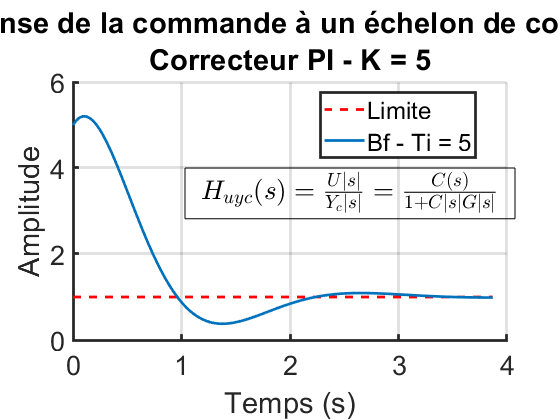

Hu_yref= feedback(cor,sys);
[u,tbf_u]=step(Hu_yref);
figure,
line(tbf_u([1 end]), ones (2,1),"Color",'red','LineStyle','--','LineWidth',2);
hold on;
plot(tbf_u,u,'LineWidth',2);
grid on;
xlabel("Temps (s)")
ylabel("Amplitude")
title({('Réponse de la commande à un échelon de consigne'),['Correcteur PI - K = ' num2str(K)]});
str = ('$H_{uyc}(s)=\frac{U|s|}{Y_c|s|}=\frac{C(s)}{1+C|s|G|s|}$');
dim = [0.5 .4 .25 .2];
annotation('textbox',dim,'String',str,'FitBoxToText',"on",'FontSize',20,'HorizontalAlignment',"center",'Interpreter',"latex");
legend({'Limite', ['Bf - K = ' num2str(K)]},"Location","best");
ax= gca;
ax.FontSize = 20;
ax.LineWidth = 2;
hold off;